T = readtable("datset Individual Assignment.xlsx") % Importing the data as a table

T = 3202×19 table
     datetime       T_mu      Po_mu      P_mu     Ff_mu     Tn_mu     Tx_mu      W_mu      Td_mu      T_var     Po_var      P_var     Ff_var     Tn_var    Tx_var    W_var     Td_var     OBSERVED     U_mu 
    ___________    _______    ______    ______    ______    ______    ______    ______    _______    _______    _______    _______    _______    ______    ______    ______    

summary(T); % Checked missing values and there are no any attributes with any missing values

Variables:

    datetime: 3202×1 datetime

        Values:

            Min       01-Jan-2010 00:00:00
            Median    21-Jul-2014 12:00:00
            Max       31-Dec-2018 00:00:00

    T_mu: 3202×1 double

        Values:

            Min       -22.675 
            Median        6.4 
            Max        26.146 

    Po_mu: 3202×1 double

        Values:

            Min         729.5 
            Median     759.21 
            Max        790.42 

    P_mu: 3202×1 double

        Values:

            Min        729.85 
            Median     759.54 
            Max        790.81 

    Ff_mu: 3202×1 double

        Values:

            Min        1.1667 
            Median      3.375 
            Max        10.792 

    Tn_mu: 3202×1 double

        Values:

            Min        -26.2  
            Median       4.7  
            Max        23.65  

    Tx_mu

rng('default')

## **Task 1**

***sub task 1***

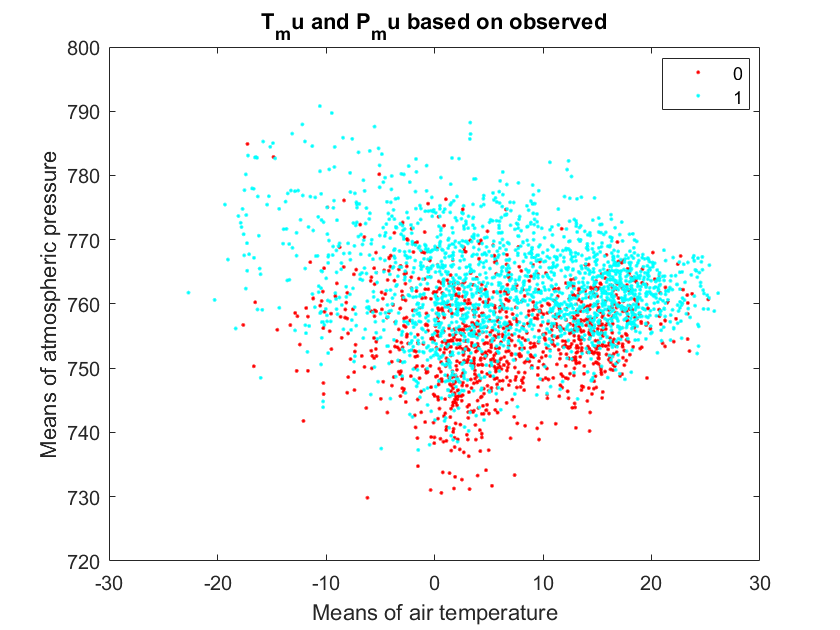

% 1) Scatter plot

figure
gscatter(T.T_mu,T.P_mu,T.OBSERVED)
xlabel('Means of air temperature')
ylabel('Means of atmospheric pressure')
title('T_mu and P_mu based on observed')

***sub task 2***

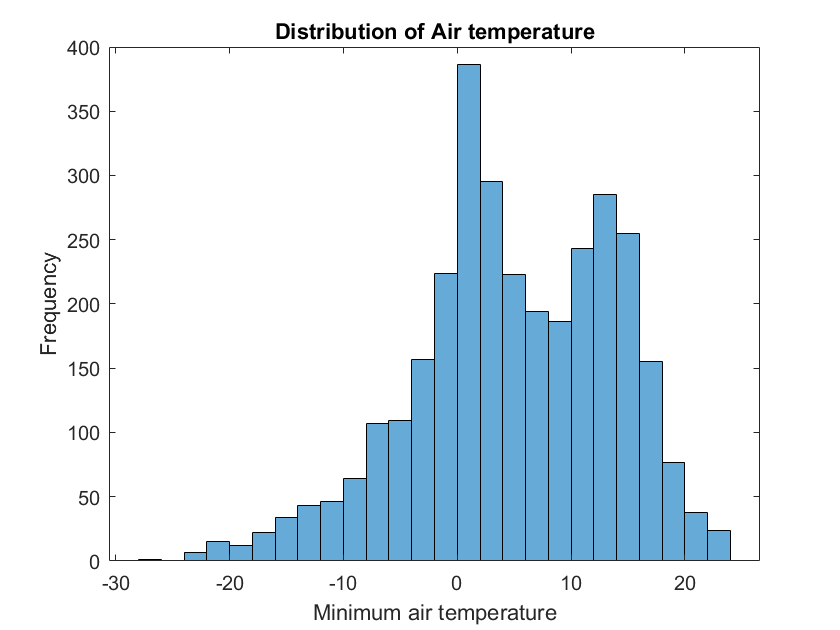

% 2) Histogram

figure
histogram(T.Tn_mu)
xlabel('Minimum air temperature')
ylabel('Frequency')
title('Distribution of Air temperature')

***sub task 3***

% 3) Max value of Td_mu based on Oberved attribute

[grpO, Obsval] = findgroups(T.OBSERVED) 

grpO =      2
     2
     1
     1
     1
     1
     1
     2
     2
     2


Obsval =      0
     1


maxTd_mu = splitapply(@max,T.Td_mu,grpO)

maxTd_mu =    20.3000
   21.4625


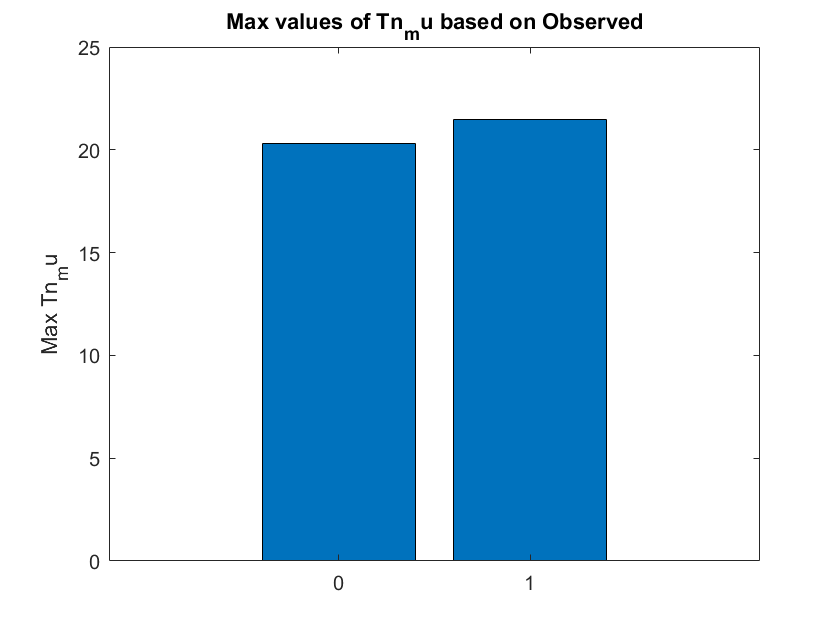

figure
bar(maxTd_mu)
xticklabels(Obsval)
ylabel("Max Tn_mu")
title('Max values of Tn_mu based on Observed')

***sub task 4***

% 4) Means of P_var based on oberved groups

meanP_var = splitapply(@mean,T.P_var,grpO)

meanP_var =     5.4376
    3.0735


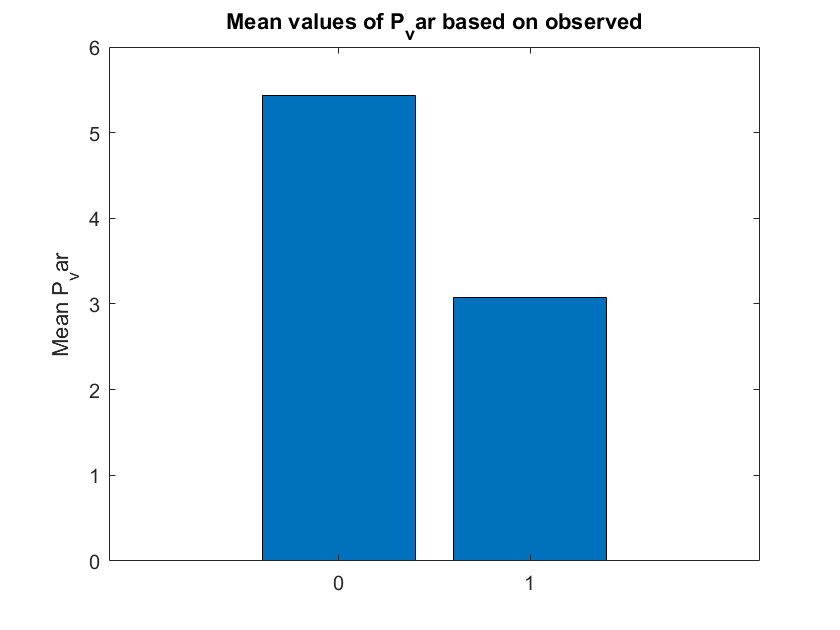

figure
bar(meanP_var)
xticklabels(Obsval)
ylabel("Mean P_var")
title('Mean values of P_var based on observed')

***sub task 5***

% 5) Seperating date into 3 columns

date = T.datetime

date = 3202×1 datetime array
   01-Jan-2010
   02-Jan-2010
   03-Jan-2010
   04-Jan-2010
   05-Jan-2010
   06-Jan-2010
   07-Jan-2010
   08-Jan-2010
   09-Jan-2010
   10-Jan-2010
   11-Jan-2010
   12-Jan-2010
   13-Jan-2010
   14-Jan-2010
   15-Jan-2010
   16-Jan-2010
   17-Jan-2010
   18-Jan-2010
   19-Jan-2010
   20-Jan-2010
   21-Jan-2010
   22-Jan-2010
   23-Jan-2010
   24-Jan-2010
   25-Jan-2010
   26-Jan-2010
   27-Jan-2010
   28-Jan-2010
   29-Jan-2010
   31-Jan-2010


a = datetime(date,'InputFormat',"dd-MMM-uuuu")

a = 3202×1 datetime array
   01-Jan-2010
   02-Jan-2010
   03-Jan-2010
   04-Jan-2010
   05-Jan-2010
   06-Jan-2010
   07-Jan-2010
   08-Jan-2010
   09-Jan-2010
   10-Jan-2010
   11-Jan-2010
   12-Jan-2010
   13-Jan-2010
   14-Jan-2010
   15-Jan-2010
   16-Jan-2010
   17-Jan-2010
   18-Jan-2010
   19-Jan-2010
   20-Jan-2010
   21-Jan-2010
   22-Jan-2010
   23-Jan-2010
   24-Jan-2010
   25-Jan-2010
   26-Jan-2010
   27-Jan-2010
   28-Jan-2010
   29-Jan-2010
   31-Jan-2010


T.YY = year(a) % seprating year and adding it to the table T

T = 3202×20 table
     datetime       T_mu      Po_mu      P_mu     Ff_mu     Tn_mu     Tx_mu      W_mu      Td_mu      T_var     Po_var      P_var     Ff_var     Tn_var    Tx_var    W_var     Td_var     OBSERVED     U_mu      YY 
    ___________    _______    ______    ______    ______    ______    ______    ______    _______    _______    _______    _______    _______    ______    ______    _

T.MM = month(a) % seperating month and adding it to the table T

T = 3202×21 table
     datetime       T_mu      Po_mu      P_mu     Ff_mu     Tn_mu     Tx_mu      W_mu      Td_mu      T_var     Po_var      P_var     Ff_var     Tn_var    Tx_var    W_var     Td_var     OBSERVED     U_mu      YY     MM
    ___________    _______    ______    ______    ______    ______    ______    ______    _______    _______    _______    _______    _______    ______    _____

T.DD = day(a) % seperating the day and adding it to the table T

T = 3202×22 table
     datetime       T_mu      Po_mu      P_mu     Ff_mu     Tn_mu     Tx_mu      W_mu      Td_mu      T_var     Po_var      P_var     Ff_var     Tn_var    Tx_var    W_var     Td_var     OBSERVED     U_mu      YY     MM    DD
    ___________    _______    ______    ______    ______    ______    ______    ______    _______    _______    _______    _______    _______    ______

T.datetime = [] % removing the datetime column from the T table

T = 3202×21 table
     T_mu      Po_mu      P_mu     Ff_mu     Tn_mu     Tx_mu      W_mu      Td_mu      T_var     Po_var      P_var     Ff_var     Tn_var    Tx_var    W_var     Td_var     OBSERVED     U_mu      YY     MM    DD
    _______    ______    ______    ______    ______    ______    ______    _______    _______    _______    _______    _______    ______    ______    ______    

***sub task 6***

% 6) Creating predictors matrix and predictor vectors for response
% variables

% creating predictors for response variables
Y1 = T.OBSERVED 

Y1 =      1
     1
     0
     0
     0
     0
     0
     1
     1
     1


Y2 = T.U_mu

Y2 =    86.2500
   82.8750
   88.7500
   91.8333
   89.0000
   89.8750
   92.1250
   85.6250
   88.8750
   92.7500



% predictors matrix
X = [T.T_mu T.Po_mu T.P_mu T.Ff_mu T.Tn_mu T.Tx_mu T.W_mu T.Td_mu T.T_var T.Po_var T.P_var T.Ff_var T.Tn_var T.Tx_var T.W_var T.Td_var T.YY T.MM T.DD]

X = 	1.0e+03 *

   -0.0129    0.7555    0.7559    0.0043   -0.0140   -0.0105    0.0194   -0.0147    0.0062    0.0093    0.0093    0.0011    0.0034    0.0003    0.1673    0.0078    2.0100    0.0010    0.0010
   -0.0174    0.7620    0.7624    0.0036   -0.0186   -0.0152    0.0279   -0.0196    0.0015    0.0011    0.0011    0.0006    0.0008    0.0000    0.0233    0.0011    2.0100    0.0010    0.0020
   -0.0126    0.7577    0.7581    0.0025   -0.0218   -0.0104    0.0193   -0.0141    0.0666    0.0171    0.0173    0.0017         0    0.1051    0.2369    0.0774    2.0100    0.0010    0.0030
   -0.0039    0.7506    0.7510    0.0034   -0.0077   -0.0024    0.0291   -0.0055    0.0035    0.0013    0.0013    0.0006    0.0004    0.0003    0.2723    0.0008    2.0100    0.0010    0.0040
   -0.0095    0.7526    0.7530    0.0037   -0.0113   -0.0042    0.0341   -0.0110    0.0215    0.0119    0.0119    0.0014    0.0224    0.0211    0.0633    0.0307    2.0100    0.0010    0.0050
   -0.0112    0.7605    0.760

## **Task 2**

***sub task 1***

% 1) Principle Component Analysis

[coeff,score,latent,~,explained]= pca(X) % As per the results of explained, the first 2 principle components cumulative variance is more than 94%, hence those two were selected

coeff =    -0.0067    0.4922   -0.0039   -0.0323    0.0805   -0.0367   -0.0199   -0.0325    0.0376   -0.0678    0.0244    0.0030   -0.1726   -0.0260    0.0262    0.0129    0.8422    0.0073   -0.0012
   -0.0184   -0.0602    0.5826   -0.2039    0.2581   -0.1102   -0.1865    0.0057    0.0194   -0.0045    0.0005   -0.0195    0.0048    0.0212    0.0084   -0.0028   -0.0034    0.0987    0.7003
   -0.0184   -0.0608    0.5828   -0.2039    0.2583   -0.1101   -0.1864    0.0054    0.0193   -0.0047    0.0003   -0.0191    0.0042    0.0217    0.0085   -0.0017   -0.0035   -0.0990   -0.7000
    0.0011   -0.0100   -0.0295    0.0337    0.0037    0.0024   -0.0236   -0.0043    0.0360    0.0403    0.0282   -0.0939   -0.3291    0.4899    0.7132   -0.3522   -0.0619    0.0001    0.0001
   -0.0065    0.4895   -0.0358   -0.0514    0.0690   -0.0243   -0.0942    0.0014    0.0190   -0.0594    0.0527   -0.1008   -0.2399   -0.0642    0.2312    0.6859   -0.3738   -0.0019    0.0007
   -0.0074    0.5078    0.0190   -0.0

score =    89.9359  -37.8463   -5.3020    2.6200   -6.3355  -13.6869    4.2009    3.2247    3.2792   -3.2102   -3.7842    1.1755   -0.3372   -0.4919    0.7556    0.2458   -0.6121   -0.0060   -0.0042
  -54.1187  -46.2131    5.6231    5.8283  -17.3942   -7.4039   -2.4967    3.9102   -1.9457   -2.0947   -4.2301   -0.4440   -0.1134   -0.3380   -0.0912   -0.1946   -0.4521    0.0145   -0.0044
  159.7424  -41.7797   18.6296   23.0646   23.1743  -33.1306   91.9323  -91.8175   22.1031    6.5444    2.5900  -10.2265    7.1730   -0.9606    2.6642    3.7738   -0.6651    0.0954   -0.0065
  194.8846  -17.8025   -3.4172    1.1759  -16.8926   -5.8028    1.0790    2.4034   -2.0758   -4.0475   -3.8015    1.8524    1.1270   -0.2324    0.0417   -1.3170    0.8212    0.0121   -0.0121
  -13.7091  -27.0421    1.8401   26.3867    0.2981  -15.3620   34.7208   -5.1013   12.7218   -0.2245   -1.8558   -6.9987    3.8853   -0.6638    0.5631    0.2152   -2.4715   -0.0527    0.0043
   45.3924  -34.8000    2.4902   -4.0

latent = 	1.0e+03 *

    8.7921
    0.3137
    0.1606
    0.1207
    0.0788
    0.0762
    0.0589
    0.0333
    0.0134
    0.0106


explained =    90.8774
    3.2430
    1.6603
    1.2473
    0.8146
    0.7873
    0.6092
    0.3443
    0.1388
    0.1090


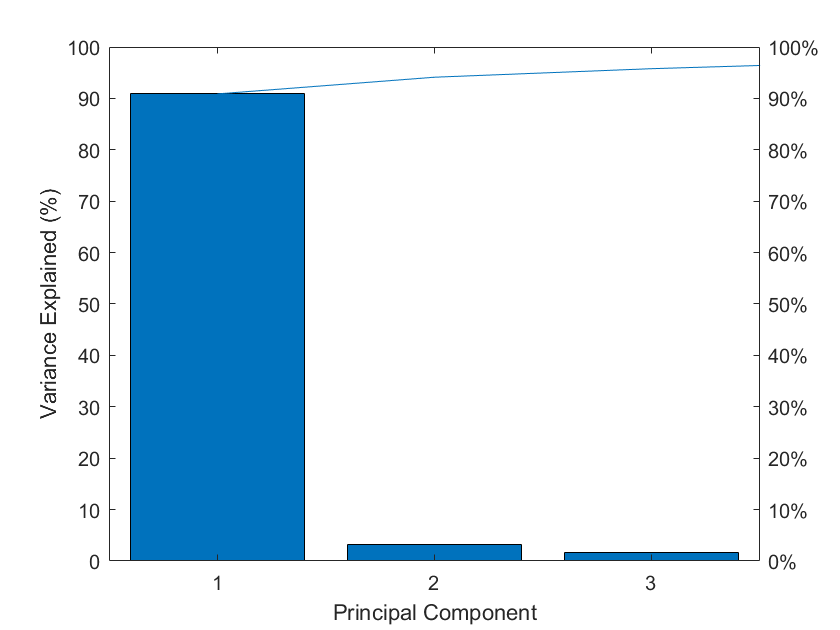

figure
pareto(explained)   
xlabel('Principal Component')
ylabel('Variance Explained (%)')

***sub task 2***

% 2) K-means clustersing for PCA dataset

[idx2,cmeans2] = kmeans(score,2)% 2 clusters

idx2 =      2
     1
     2
     2
     1
     1
     1
     1
     1
     1


cmeans2 =   -36.3294   -0.0085   -0.0127    0.0476   -0.0023   -0.0188    0.0432    0.0120    0.0107   -0.0170    0.0025   -0.0062    0.0058    0.0032   -0.0087    0.0024   -0.0019   -0.0010   -0.0000
  174.0262    0.0409    0.0609   -0.2281    0.0111    0.0902   -0.2067   -0.0577   -0.0515    0.0813   -0.0118    0.0297   -0.0278   -0.0154    0.0415   -0.0114    0.0090    0.0047    0.0001


[idx3,cmeans3] = kmeans(score,3)% 3 clusters

idx3 =      3
     1
     3
     2
     1
     3
     1
     1
     1
     1


cmeans3 =   -46.9189    0.1108    0.2595   -0.1055    0.0743    0.0130    0.0675   -0.0005    0.0260    0.0034    0.0472    0.0105   -0.0467   -0.0174    0.0067    0.0019    0.0005    0.0028   -0.0001
  256.0032    0.6748    1.8474   -1.9186    0.9503   -0.0023   -0.0382    0.1710   -0.0141    0.4672    0.2102    0.2391   -0.2613   -0.2062   -0.0522   -0.0013    0.0269    0.0083   -0.0000
   75.0683   -0.6413   -1.5987    1.0732   -0.6104   -0.0458   -0.2277   -0.0602   -0.0879   -0.1814   -0.2451   -0.1244    0.2617    0.1370   -0.0050   -0.0062   -0.0114   -0.0132    0.0002


[idx4,cmeans4] = kmeans(score,4)% 4 clusters

idx4 =      4
     2
     4
     4
     1
     1
     2
     2
     2
     2


cmeans4 =    18.5400    0.1971   -1.3669    1.3692   -0.0941   -0.0136    0.0689   -0.0599    0.0588   -0.1845   -0.1331   -0.1494    0.2591    0.1184   -0.0547   -0.0037   -0.0249   -0.0135   -0.0001
  -55.4479   -0.0805    0.5124   -0.4489    0.0492    0.0182    0.0169    0.0272   -0.0058    0.0266    0.0545    0.0490   -0.0924   -0.0351    0.0102    0.0047    0.0053    0.0041   -0.0000
  304.6173    0.4154    1.4159   -3.4215    1.4251    0.1262    0.5816    0.3921    0.1015    0.0482    0.4203    0.1063   -0.5760   -0.2253    0.0468    0.0336    0.0297    0.0179   -0.0018
  138.5068   -0.1242   -0.4024    0.7744   -0.5603   -0.1097   -0.4235   -0.1564   -0.1215    0.2111   -0.1607    0.0084    0.1593    0.0237    0.0394   -0.0281    0.0118   -0.0004    0.0010


[idx5,cmeans5] = kmeans(score,5)% 5 clusters

idx5 =      3
     5
     3
     3
     5
     1
     5
     5
     5
     5


cmeans5 =    21.0623    0.9393   -1.4659    1.4444   -0.0490   -0.0143   -0.0423   -0.0017    0.0513   -0.1497   -0.1371   -0.1515    0.2436    0.1212   -0.0515    0.0088   -0.0255   -0.0148   -0.0001
  305.2463    0.4697    1.4268   -3.3912    1.4883    0.1399    0.5589    0.4129    0.0860    0.0025    0.4363    0.0959   -0.5747   -0.2332    0.0550    0.0356    0.0266    0.0182   -0.0019
  139.0334   -0.2785   -0.4516    0.7977   -0.5839   -0.0509   -0.4191   -0.1904   -0.1228    0.2273   -0.1695    0.0163    0.1528    0.0255    0.0381   -0.0290    0.0136   -0.0005    0.0011
  -57.1677   14.2668    1.1639   -0.3194    0.6307   -0.5817    0.7358   -0.2209    0.0522   -0.0748    0.1635    0.1041   -0.1848   -0.0930   -0.0027   -0.0466    0.0106    0.0039    0.0001
  -51.5512  -16.3400   -0.2033   -0.5743   -0.6294    0.6513   -0.6865    0.2633   -0.0581    0.1019   -0.0700   -0.0214    0.0401    0.0342    0.0184    0.0513   -0.0018    0.0044   -0.0002




pc1 = score(:,1) % Principle component 1 data

pc1 =    89.9359
  -54.1187
  159.7424
  194.8846
  -13.7091
   45.3924
  -33.7830
  -57.3343
  -63.3178
  -62.1080


pc2 = score(:,2) % Principle compenent 2 data

pc2 =   -37.8463
  -46.2131
  -41.7797
  -17.8025
  -27.0421
  -34.8000
  -32.5822
  -46.6305
  -45.8077
  -43.0440


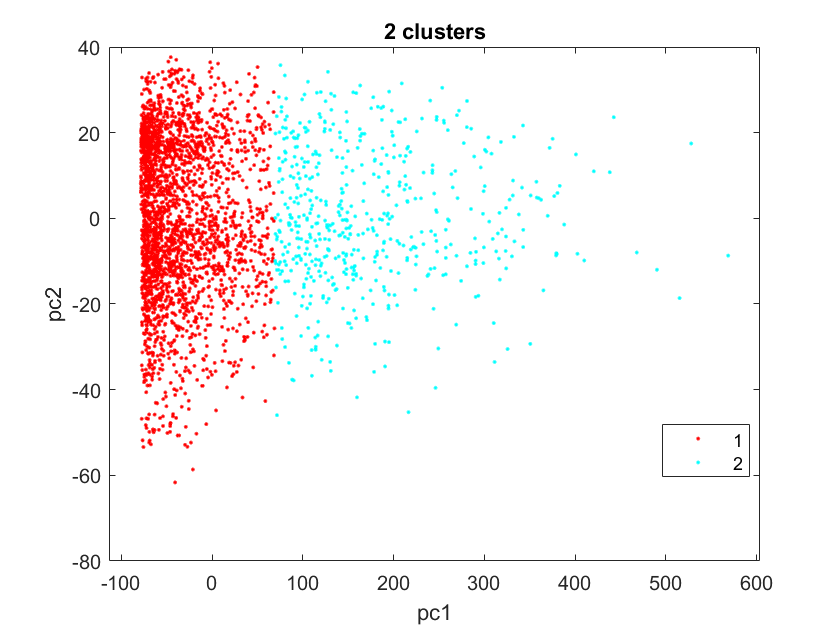


figure %2D scatter plot for 2 clusters
gscatter(pc1,pc2,idx2)
title('2 clusters')

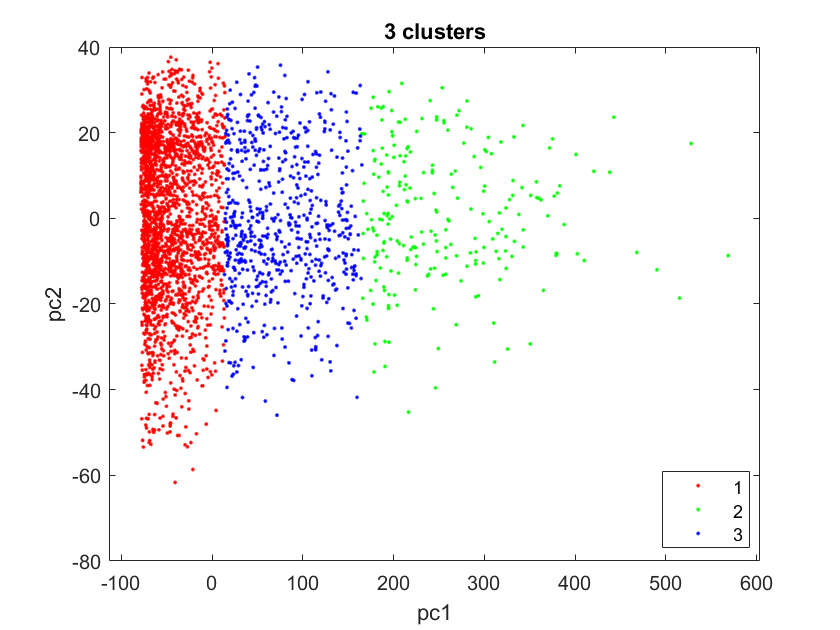


figure %2D scatter plot for 3 clusters
gscatter(pc1,pc2,idx3)
title('3 clusters')

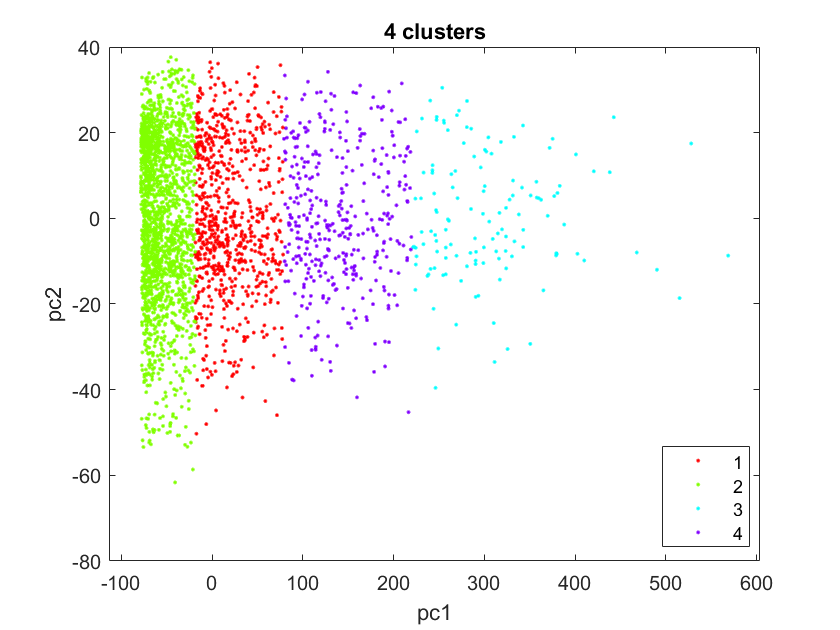


figure %2D scatter plot for 4 clusters
gscatter(pc1,pc2,idx4)
title('4 clusters')

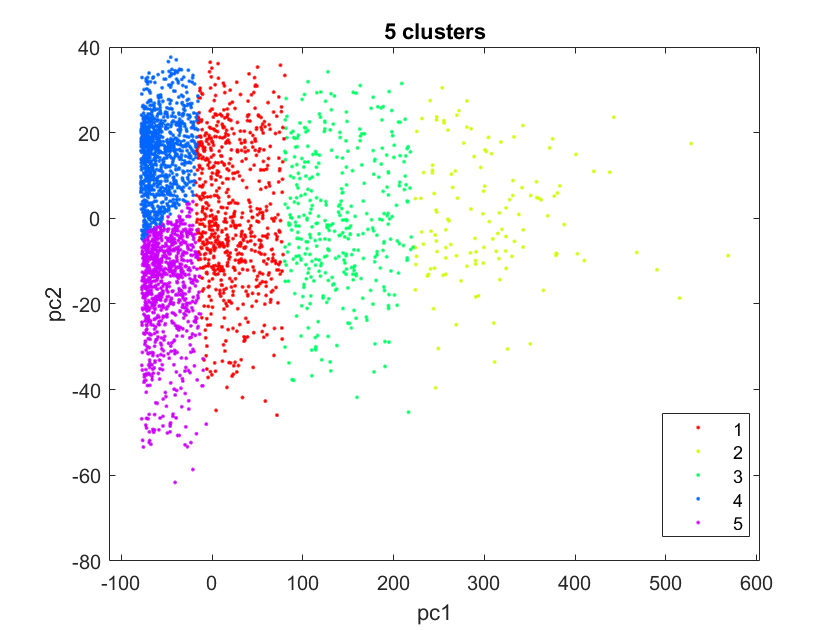


figure %2D scatter plot for 5 clusters
gscatter(pc1,pc2,idx5)
title('5 clusters')


% deciding the optimal number of clusters using silhouette as the
% evaluation criteria.

E = evalclusters(X,'kmeans','silhouette','klist',[2:5]) 

E =   SilhouetteEvaluation with properties:

    NumObservations: 3202
         InspectedK: [2 3 4 5]
    CriterionValues: [0.8393 0.7436 0.6235 0.5221]
           OptimalK: 2


kbest = E.OptimalK

kbest = 2

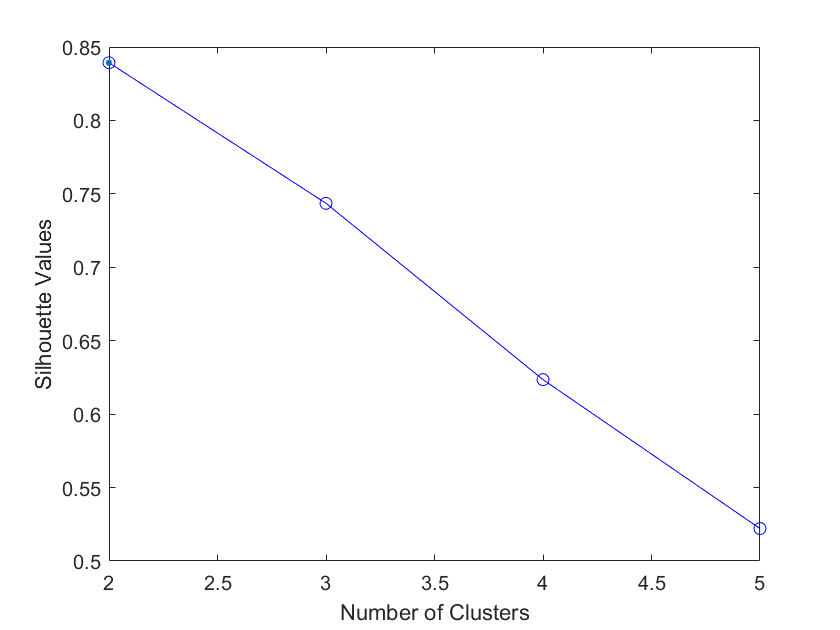

figure
plot(E)


% deciding the optimal number of clusters using CalinskiHarabasz as the
% evaluation criteria.

E2 = evalclusters(X,'kmeans','CalinskiHarabasz', 'klist',[2:5]) 

E2 =   CalinskiHarabaszEvaluation with properties:

    NumObservations: 3202
         InspectedK: [2 3 4 5]
    CriterionValues: [6.0404e+03 5.6797e+03 5.4302e+03 4.9049e+03]
           OptimalK: 2


kbest2 = E2.OptimalK

kbest2 = 2

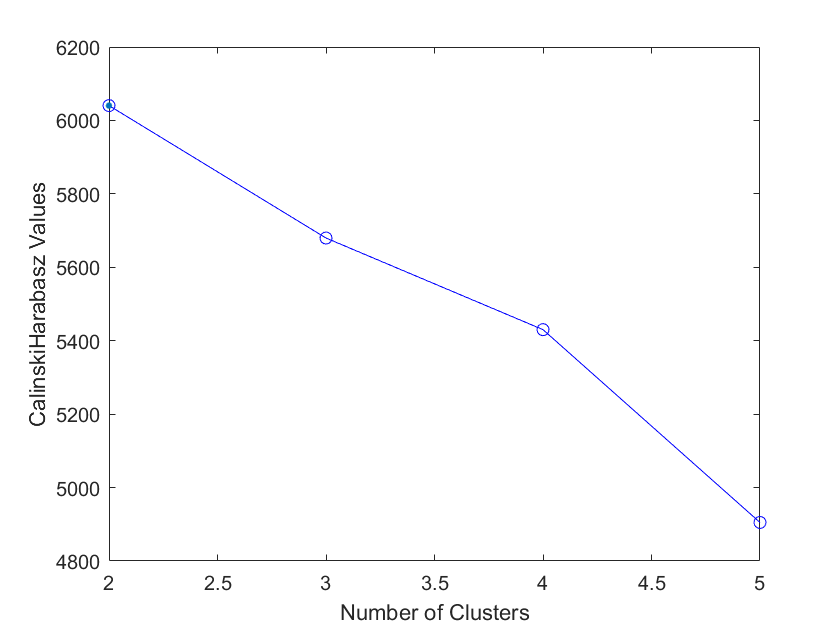

figure
plot(E2)


% deciding the optimal number of clusters using DaviesBouldin as the
% evaluation criteria.
E3 = evalclusters(X,'kmeans','DaviesBouldin', 'klist',[2:5]) 

E3 =   DaviesBouldinEvaluation with properties:

    NumObservations: 3202
         InspectedK: [2 3 4 5]
    CriterionValues: [0.5790 0.6846 0.8107 0.9148]
           OptimalK: 2


kbest3 = E3.OptimalK

kbest3 = 2

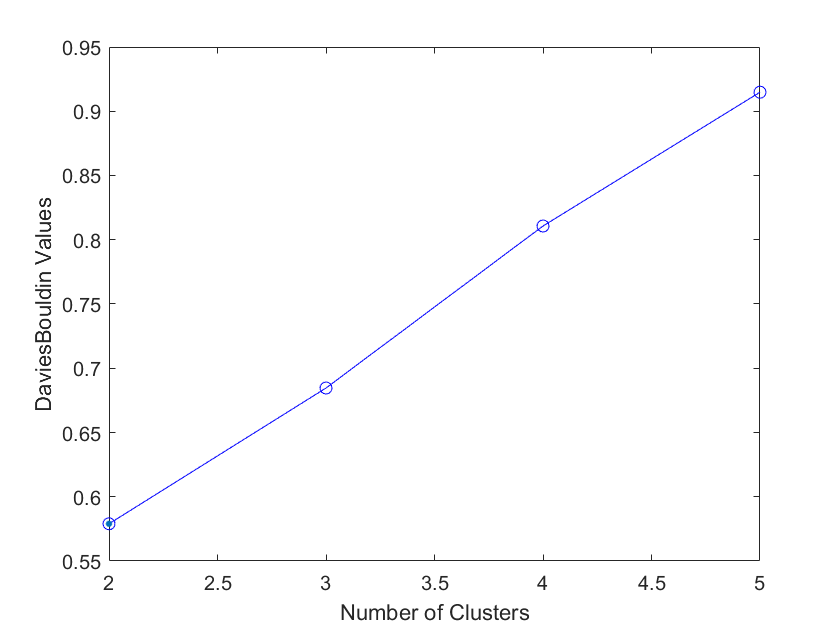

figure
plot(E3)


% As per the 3 criterias that used to identify the optimal number of
% clcuters, since it gives 2 clusters as the optimal number, it is decided
% that 2 clusters is the best choice.


***sub task 3***

% 3) Hierarchical Clustering

cosD = pdist(score,"cosine")

cosD =     1.3931    0.2437    0.0551    0.9598    0.0527    1.3252    1.4174    1.4951    1.5008    0.2281    1.7286    1.6533    0.0561    1.2068    0.0836    0.1176    0.1241    0.0762    0.4182    1.5728    1.3461    1.5401    1.4639    1.1503    1.3392    1.1330    1.3896    1.5753    1.5877    1.5264    0.1603    0.0468    1.3960    1.6936    1.6233    1.6536    1.6490    1.6490    1.5915    1.6248    1.6237    0.0281    1.5708    1.5909    1.5910    0.0345    1.0044    0.0477    0.0406    1.3216


clustTreeCos = linkage(cosD,"average")

clustTreeCos = 	1.0e+03 *

    2.7880    3.1500    0.0000
    2.7720    3.1640    0.0000
    0.4200    0.7200    0.0000
    0.5260    0.9340    0.0000
    0.4280    0.8120    0.0000
    1.0460    1.0470    0.0000
    0.3140    0.3190    0.0000
    2.8060    3.1980    0.0000
    0.5700    0.5930    0.0000
    0.2900    0.9640    0.0000


cutoff = 0.6

cutoff = 0.6000

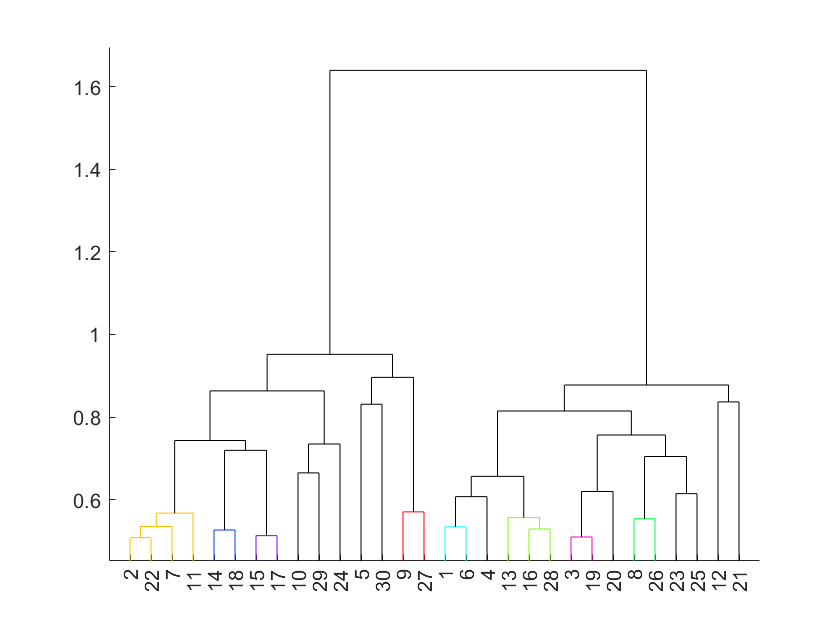

dendrogram(clustTreeCos,'ColorThreshold',cutoff)

% As per the dendrogram, it shows 19 clusters when the threshhold is 0.6. To
% evaluate quality of this cluster option, we can use silhoutte
% coefficient.
hidxcos = cluster(clustTreeCos,'criterion','distance','cutoff',0.6)

hidxcos =     13
     9
    13
    13
    18
    13
     9
     9
     9
     9


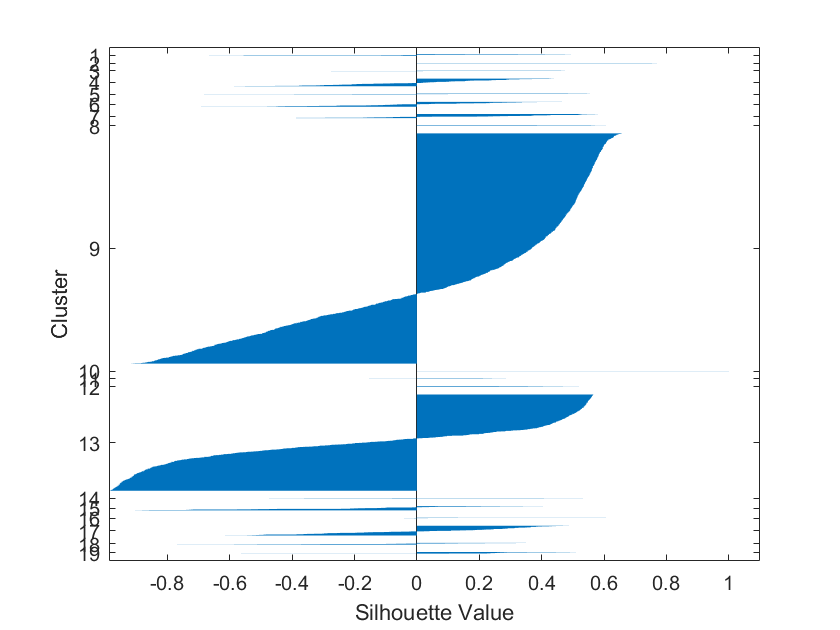

silhtreecos =    -0.4320
    0.0082
    0.2002
    0.5459
    0.2160
   -0.8630
   -0.3669
    0.1308
    0.0918
    0.0385


h =   Figure (12) with properties:

      Number: 12
        Name: ''
       Color: [1 1 1]
    Position: [360 198 560 420]
       Units: 'pixels'

  Show all properties


[silhtreecos,h] = silhouette(score,hidxcos)


f = @(score,k) clusterdata(score,'linkage','average','Distance','cosine','maxclust',k);
Eva = evalclusters(score,f,'silhouette','klist',[2:19])

Eva =   SilhouetteEvaluation with properties:

    NumObservations: 3202
         InspectedK: [2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19]
    CriterionValues: [0.6573 0.3433 0.1133 0.1085 0.0861 0.0811 0.0810 0.0993 0.1038 0.1003 0.0825 0.0733 0.0682 0.0544 0.0726 0.0689 0.0592 0.0612]
           OptimalK: 2



%As per the evaluation criteria it is shown that the optimal number of
%clusters is 2.


***sub task 4***

% 4) Gaussian Mixture Model

x = score(:,1:2)

x =    89.9359  -37.8463
  -54.1187  -46.2131
  159.7424  -41.7797
  194.8846  -17.8025
  -13.7091  -27.0421
   45.3924  -34.8000
  -33.7830  -32.5822
  -57.3343  -46.6305
  -63.3178  -45.8077
  -62.1080  -43.0440


k = 3 % number of clusters

k = 3

options = statset('MaxIter',1000); % number of iterations
gm = fitgmdist(x,k,'Options',options);
P = posterior(gm,x) % estimating cluster membership posterior probabilities

P =     0.9998    0.0000    0.0002
    0.0177    0.3659    0.6164
    1.0000    0.0000    0.0000
    1.0000         0    0.0000
    0.0731    0.0000    0.9269
    0.8672    0.0000    0.1328
    0.0413    0.0000    0.9587
    0.0120    0.5943    0.3937
    0.0068    0.8153    0.1779
    0.0082    0.7939    0.1979



prob_1 = P(8,1) % probability of 8th observation belongs to cluster 1

prob_1 = 0.0120

prob_2 = P(8,2) % probability of 8th observation belongs to cluster 2

prob_2 = 0.5943

prob_3 = P(8,3) % probability of 8th observation belongs to cluster 3

prob_3 = 0.3937

## **Task 3**

***sub task 1***

% 1) Splitting the data into training and testing

rng(1)
cv = cvpartition(length(X),'holdout',0.3)

cv = Hold-out cross validation partition
   NumObservations: 3202
       NumTestSets: 1
         TrainSize: 2242
          TestSize: 960


% Training set
Xtrain = X(training(cv),:);
Y2train = Y2(training(cv),:);

% Testing set
Xtest = X(test(cv),:);
Y2test = Y2(test(cv),:);


***sub task 2***

% 2) Linear regression model

mdl = fitlm(Xtrain,Y2train,'linear')

mdl = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17 + x18 + x19

Estimated Coefficients:
                   Estimate         SE         tStat        pValue  
                   _________    __________    ________    __________

    (Intercept)       166.81         24.17      6.9014    6.6941e-12
    x1               -4.2234      0.066469     -63.539             0
    x2                3.2381        1.4387      2.2508      0.024499
    x3               -3.2752         1.438     -2.2776      0.022842
    x4              -0.25393      0.031883     -7.9643     2.628e-15
    x5               0.24538      0.041928      5.8525    5.5615e-09
    x6               

% Even though all the X attributes are not significant, since the R squared
% value is 0.987 the model fitted is a good one, but if we want to improve
% the model we need to remove the attributes that is not significant
% according to the p-value.


***sub task 3***

% 3) Second linear regression model

mdl2 = fitlm(Xtrain(:,3:19),Y2train,'linear') % as instructed the first 2 columns in Xtrain wasn't considered.

mdl2 = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17

Estimated Coefficients:
                    Estimate          SE           tStat         pValue   
                   ___________    __________    ___________    ___________

    (Intercept)         274.46        40.443         6.7865     1.4686e-11
    x1               -0.073966     0.0067534        -10.952     3.1648e-27
    x2                -0.50481      0.053077        -9.5108     4.7279e-21
    x3                 -1.5549      0.051858        -29.984    3.5105e-166
    x4                 -2.2643      0.045768        -49.473              0
    x5                -0.11084     0.0058362        -18.992     1.1653e-74
 

% Compared to the mdl the mdl2 R squared value is 0.962 which is less by 0.025 and the
% root mean squared error is high.

***sub task 4***

% 4) MSE over test data

Y2predicted_test= mdl.predict(Xtest) % Predicting Y2 based on the first model

Y2predicted_test =    88.4346
   89.8562
   84.5167
   86.6170
   93.8567
   87.4198
   87.1921
   87.0827
   83.0481
   91.2641



Y2predicted_test2= mdl2.predict(Xtest(:,3:19)) % Predicting the Y2 using the second model

Y2predicted_test2 =    75.8147
   90.6428
   76.1820
   83.7550
   93.3622
   85.3232
   83.4670
   89.6749
   72.9493
   95.0164



MSEtest = immse(Y2test,Y2predicted_test) % Calculating the mean squared error for the 1st model

MSEtest = 2.1855


MSEtest2 = immse(Y2test,Y2predicted_test2) % Calculating the mean squared error for the 2nd model

MSEtest2 = 5.8113


% As per the MSE values of 2 models, since the MSE value is less in model
% 1, out of the 2 models that we fitted, the first model has a better
% performance over the test data.

***sub task 5***

% 5) Principle Component Regression

% considering first 2 principle components
[coeff,scoreTrain,~,~,explained,mu] = pca(Xtrain)

coeff =    -0.0080    0.4910    0.0001   -0.0206    0.0930   -0.0006   -0.0256   -0.0332    0.0368   -0.0716    0.0234   -0.0056   -0.1705   -0.0100    0.0149    0.0135    0.8434    0.0033   -0.0007
   -0.0194   -0.0664    0.5862   -0.1515    0.2969   -0.0130   -0.1955    0.0134    0.0227   -0.0062    0.0028   -0.0222    0.0067    0.0221    0.0067   -0.0027   -0.0034    0.0826    0.7024
   -0.0194   -0.0671    0.5864   -0.1515    0.2970   -0.0129   -0.1955    0.0134    0.0229   -0.0065    0.0025   -0.0219    0.0064    0.0222    0.0067   -0.0019   -0.0036   -0.0828   -0.7021
    0.0011   -0.0100   -0.0300    0.0312   -0.0052    0.0034   -0.0240   -0.0024    0.0404    0.0452    0.0373   -0.1072   -0.3006    0.5367    0.6791   -0.3720   -0.0538   -0.0006   -0.0001
   -0.0079    0.4897   -0.0296   -0.0452    0.0725    0.0036   -0.1001   -0.0050    0.0232   -0.0550    0.0543   -0.0954   -0.2266   -0.0498    0.2721    0.6807   -0.3674   -0.0021    0.0005
   -0.0087    0.5063    0.0219    0.0

scoreTrain =    89.4523  -37.2092   -5.4568    2.5940   -1.4682  -15.1384    4.5847    3.5726    3.4270   -2.8901   -4.0764    0.8507   -0.4056   -0.5348    0.7885    0.2222   -0.6195    0.0021   -0.0044
  -54.6044  -46.0124    5.3576    5.6131  -14.3388  -13.5502   -1.3272    4.2091   -1.7378   -1.7738   -4.3940   -0.6759   -0.0594   -0.4791   -0.0794   -0.1618   -0.4864    0.0256   -0.0049
  159.3916  -42.0656   16.0181   29.2833   39.7295  -19.9590   91.0320  -90.2092   16.3711    6.0943    2.0588  -10.2149    6.7536   -1.3289    2.8069    3.2434   -0.5410    0.0134   -0.0080
  194.3234  -16.7879   -2.6772    0.1854  -14.1248  -11.7707    2.2004    2.6988   -1.8254   -3.7393   -4.0061    1.6426    1.0784   -0.3081   -0.0265   -1.3221    0.7960    0.0138   -0.0115
  -34.3008  -32.2068   -9.4136  -10.4874   -2.2727   -9.0924    0.7075    2.1896   -0.4689   -3.2798   -4.6328   -0.7805   -0.9504    0.2471    0.9281   -0.3978   -0.0708    0.0722   -0.0075
  -62.6484  -43.0411   16.6071  

explained =    90.9706
    3.1629
    1.6732
    1.1899
    0.8301
    0.7762
    0.6132
    0.3691
    0.1409
    0.1075


mu = 	1.0e+03 *

    0.0067    0.7594    0.7598    0.0036    0.0049    0.0086    0.0242    0.0033    0.0042    0.0041    0.0041    0.0013    0.0036    0.0039    0.0785    0.0026    2.0141    0.0065    0.0158



scoreTrain2comp = scoreTrain(:,1:2) % first 2 pc

scoreTrain2comp =    89.4523  -37.2092
  -54.6044  -46.0124
  159.3916  -42.0656
  194.3234  -16.7879
  -34.3008  -32.2068
  -62.6484  -43.0411
   26.7255  -35.6639
  -73.8405  -22.7971
  -54.6623  -22.9973
   92.5237  -22.2854



mdl_pc2 = fitlm(scoreTrain2comp,Y2train,'linear')

mdl_pc2 = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                   Estimate       SE         tStat       pValue  
                   ________    _________    _______    __________

    (Intercept)      80.696      0.24025     335.88             0
    x1             0.025255    0.0025415     9.9373    8.4327e-23
    x2             -0.16863      0.01363    -12.373    4.6492e-34


Number of observations: 2242, Error degrees of freedom: 2239
Root Mean Squared Error: 11.4
R-squared: 0.101,  Adjusted R-Squared: 0.1
F-statistic vs. constant model: 126, p-value = 1.51e-52



% considering first 3 principle components
scoreTrain3comp = scoreTrain(:,1:3) % first 3 pc

scoreTrain3comp =    89.4523  -37.2092   -5.4568
  -54.6044  -46.0124    5.3576
  159.3916  -42.0656   16.0181
  194.3234  -16.7879   -2.6772
  -34.3008  -32.2068   -9.4136
  -62.6484  -43.0411   16.6071
   26.7255  -35.6639   15.3966
  -73.8405  -22.7971    3.7642
  -54.6623  -22.9973    3.5338
   92.5237  -22.2854   10.7196



mdl_pc3 = fitlm(scoreTrain3comp,Y2train,'linear')

mdl_pc3 = Linear regression model:
    y ~ 1 + x1 + x2 + x3

Estimated Coefficients:
                   Estimate       SE         tStat       pValue  
                   ________    _________    _______    __________

    (Intercept)      80.696      0.21324     378.42             0
    x1             0.025255    0.0022558     11.196    2.3869e-28
    x2             -0.16863     0.012098    -13.939    2.0528e-42
    x3             -0.40879     0.016633    -24.577    2.799e-118


Number of observations: 2242, Error degrees of freedom: 2238
Root Mean Squared Error: 10.1
R-squared: 0.292,  Adjusted R-Squared: 0.291
F-statistic vs. constant model: 308, p-value = 2.49e-167



% considering first 3 principle components
scoreTrain4comp = scoreTrain(:,1:4) % first 4 pc

scoreTrain4comp =    89.4523  -37.2092   -5.4568    2.5940
  -54.6044  -46.0124    5.3576    5.6131
  159.3916  -42.0656   16.0181   29.2833
  194.3234  -16.7879   -2.6772    0.1854
  -34.3008  -32.2068   -9.4136  -10.4874
  -62.6484  -43.0411   16.6071  -15.9514
   26.7255  -35.6639   15.3966   -9.0707
  -73.8405  -22.7971    3.7642  -13.2798
  -54.6623  -22.9973    3.5338  -15.3619
   92.5237  -22.2854   10.7196  -15.6066



mdl_pc4 = fitlm(scoreTrain4comp,Y2train,'linear')

mdl_pc4 = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4

Estimated Coefficients:
                   Estimate       SE         tStat       pValue   
                   ________    _________    _______    ___________

    (Intercept)      80.696      0.17279     467.02              0
    x1             0.025255    0.0018279     13.817     9.9215e-42
    x2             -0.16863    0.0098027    -17.203     2.1834e-62
    x3             -0.40879     0.013478    -30.331    1.4615e-169
    x4             -0.54704     0.015982    -34.228    7.5516e-207


Number of observations: 2242, Error degrees of freedom: 2237
Root Mean Squared Error: 8.18
R-squared: 0.535,  Adjusted R-Squared: 0.535
F-statistic vs. constant model: 645, p-value = 0



% testing data as per Principle components
scoreTest2comp = (Xtest-mu)*coeff(:,1:2) % for the first 2 pc

scoreTest2comp =   -14.1702  -27.1383
   44.8660  -34.3282
  -57.7545  -46.8373
  -63.8228  -45.8979
  -17.3493  -23.3097
   68.1770  -25.5274
  -69.8841  -46.0414
  -69.8266  -52.6918
  -43.5264  -46.1270
  -53.4171  -28.0605


scoreTest3comp = (Xtest-mu)*coeff(:,1:3) % for the first 3 pc

scoreTest3comp =   -14.1702  -27.1383   -0.4086
   44.8660  -34.3282    2.6427
  -57.7545  -46.8373   -0.2659
  -63.8228  -45.8979   16.0871
  -17.3493  -23.3097   12.4575
   68.1770  -25.5274   28.0702
  -69.8841  -46.0414   27.1360
  -69.8266  -52.6918   25.9747
  -43.5264  -46.1270   31.8544
  -53.4171  -28.0605  -17.0134


scoreTest4comp = (Xtest-mu)*coeff(:,1:4) % for the first 3 pc

scoreTest4comp =   -14.1702  -27.1383   -0.4086   28.0340
   44.8660  -34.3282    2.6427   -3.8805
  -57.7545  -46.8373   -0.2659   15.3875
  -63.8228  -45.8979   16.0871   -3.0346
  -17.3493  -23.3097   12.4575   -2.6902
   68.1770  -25.5274   28.0702   -4.5651
  -69.8841  -46.0414   27.1360  -12.6086
  -69.8266  -52.6918   25.9747  -13.4352
  -43.5264  -46.1270   31.8544   -2.8059
  -53.4171  -28.0605  -17.0134   -3.6084




% Calculating MSE for each model
Y2predicted_pc2= mdl_pc2.predict(scoreTest2comp) % Y2 prediction for PCR model 1

Y2predicted_pc2 =    84.9151
   87.6185
   87.1363
   86.8246
   84.1891
   86.7231
   86.6957
   87.8187
   87.3758
   84.0794


Y2predicted_pc3= mdl_pc3.predict(scoreTest3comp) % Y2 prediction for PCR model 2

Y2predicted_pc3 =    85.0821
   86.5382
   87.2450
   80.2484
   79.0967
   75.2484
   75.6029
   77.2006
   74.3542
   91.0342


Y2predicted_pc4= mdl_pc4.predict(scoreTest4comp) % Y2 prediction for PCR model 3

Y2predicted_pc4 =    69.7464
   88.6610
   78.8274
   81.9084
   80.5684
   77.7457
   82.5003
   84.5501
   75.8891
   93.0082



MSEtest_pc2 = immse(Y2test,Y2predicted_pc2) % Calculating the mean squared error for the 1st PCR model 1

MSEtest_pc2 = 122.7393

MSEtest_pc3 = immse(Y2test,Y2predicted_pc3) % Calculating the mean squared error for the 2nd PCR model 2

MSEtest_pc3 = 94.5255

MSEtest_pc4 = immse(Y2test,Y2predicted_pc4) % Calculating the mean squared error for the 3rd PCR model 3

MSEtest_pc4 = 64.8524


% As per the MSE values for the 3 different PCR, the model with 4 principle
% components make better predictions than other two.

## **Task 4**

***sub task 1***

% 1) Splitting the Y1 attribute into testing and training

% Training set
Y1train = Y1(training(cv),:);

% Testing set
Y1test = Y1(test(cv),:);

***sub task 2***

% 2) Logistic regression model

mdl_lr = fitglm(Xtrain,Y1train,"PredictorVars",["T.T_mu", "T.Po_mu", "T.P_mu", "T.Ff_mu", "T.Tn_mu", "T.Tx_mu", "T.W_mu", "T.Td_mu", "T.T_var", "T.Po_var", "T.P_var", "T.Ff_var", "T.Tn_var", "T.Tx_var", "T.W_var", "T.Td_var", "T.YY", "T.MM", "T.DD"],"ResponseVar","Observed", 'Distribution','binomial','Link','logit')

mdl_lr = Generalized linear regression model:
    logit(Observed) ~ 1 + T.T_mu + T.Po_mu + T.P_mu + T.Ff_mu + T.Tn_mu + T.Tx_mu + T.W_mu + T.Td_mu + T.T_var + T.Po_var + T.P_var + T.Ff_var + T.Tn_var + T.Tx_var + T.W_var + T.Td_var + T.YY + T.MM + T.DD
    Distribution = Binomial

Estimated Coefficients:
                    Estimate         SE         tStat        pValue  
                   __________    __________    ________    __________

    (Intercept)       -254.63         48.44     -5.2567    1.4667e-07
    T.T_mu            0.31237       0.13765      2.2694      0.023247
    T.Po_mu           -3.7258        2.7732     -1.3435       0.17911
    T.P_mu             3.8318        2.7723      1.3822       0.16691
    T.Ff_mu          -0.35175      0.063208     -5.5


ptest = predict(mdl_lr,Xtest) % estimate the probabilities using the mdl_lr model for the test data

ptest =     0.5417
    0.7879
    0.8341
    0.9155
    0.9076
    0.9423
    0.9806
    0.9131
    0.9630
    0.0960


***sub task 3***

% 3) Classification tree 

t = fitctree(scoreTrain3comp,Y1train) % the classification tree for the first 3 principle components

t =   ClassificationTree
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0 1]
           ScoreTransform: 'none'
          NumObservations: 2242


  Properties, Methods



Y1_t = predict(t,scoreTest3comp) % Under the task 4 Principle components that converted to a testing data is predicted using the t classification model

Y1_t = 960×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0


***sub task 4***

% 4) Model performance

[xxtest,yytest,Tresholds,auctest] = perfcurve(Y1test,ptest,1) % Standard ROC curve using ptest

xxtest = 961×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


yytest = 961×1
         0
    0.0016
    0.0032
    0.0048
    0.0064
    0.0080
    0.0096
    0.0112
    0.0128
    0.0144


Tresholds = 961×1
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.9999
    0.9999
    0.9998
    0.9997
    0.9997


auctest = 0.8603


[xxtest_t,yytest_t,Tresholds_t,auctest_t] = perfcurve(Y1test,Y1_t,1) % Standard ROC curve using Y1_t

xxtest_t = 3×1
         0
    0.3994
    1.0000


yytest_t = 3×1
         0
    0.7384
    1.0000


Tresholds_t = 3×1
     1
     1
     0


auctest_t = 0.6695


Performace_LR = auctest % Performance of Logistic regression model

Performace_LR = 0.8603

Perfomance_CT = auctest_t % Performance of Classification Tree

Perfomance_CT = 0.6695


% As per the values of Performance of logistic regression and classification
% tree, the auctest value is higher in LR which is 0.8 hence that is the
% better model than the classification tree.

***sub task 5***

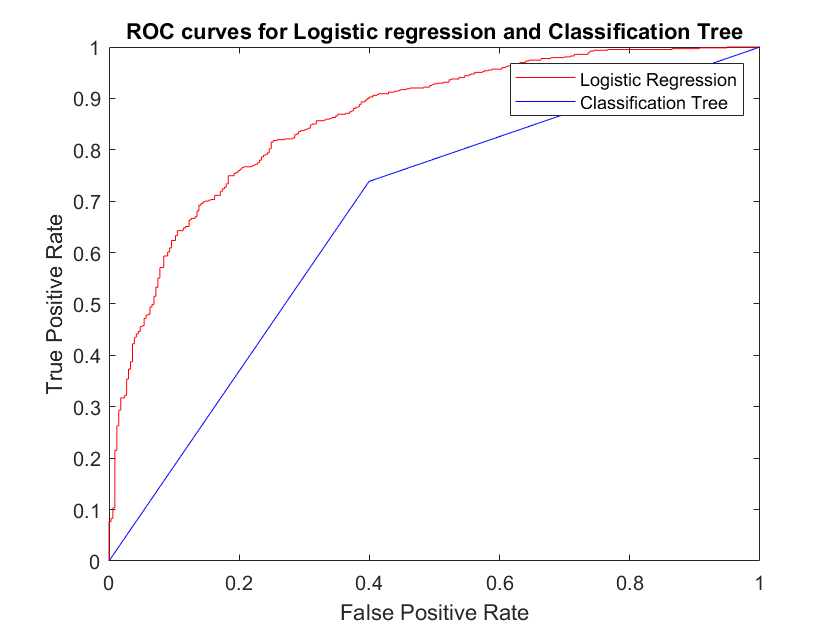

% 5) ROC curves

plot(xxtest,yytest,'r') % Plotting the ROC curve for logistic regression
xlabel('False Positive Rate')
ylabel('True Positive Rate')
title('ROC curves for Logistic regression and Classification Tree')
hold on
plot(xxtest_t,yytest_t,'b') % Plotting the ROC curve for classification tree
legend('Logistic Regression', 'Classification Tree')
hold off

## TASK 5

***sub task 1***

% 1) Creating 3 different models

% Data partition as per K fold

rng(1)
cv2 = cvpartition(length(Xtrain),'Kfold',4)

cv2 = K-fold cross validation partition
   NumObservations: 2242
       NumTestSets: 4
         TrainSize: 1682  1681  1681  1682
          TestSize: 560  561  561  560

resp = categorical(Y1train)

resp = 2242×1 categorical array
     1 
     1 
     0 
     0 
     0 
     1 
     1 
     1 
     0 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     0 
     0 
     0 
     1 
     1 
     0 
     1 
     1 
     1 
     1 
     1 



% SVM model

mdlSVM = fitcsvm(Xtrain,resp, 'Standardize',true,'KernelFunction', 'gaussian', 'KernelScale', 'auto', 'CVPartition', cv2)

mdlSVM =   ClassificationPartitionedModel
    CrossValidatedModel: 'SVM'
         PredictorNames: {'x1'  'x2'  'x3'  'x4'  'x5'  'x6'  'x7'  'x8'  'x9'  'x10'  'x11'  'x12'  'x13'  'x14'  'x15'  'x16'  'x17'  'x18'  'x19'}
           ResponseName: 'Y'
        NumObservations: 2242
                  KFold: 4
              Partition: [1×1 cvpartition]
             ClassNames: [0    1]
         ScoreTransform: 'none'


  Properties, Methods



% Classification tree with minimum number of samples

t1 = fitctree(Xtrain,resp,'MinLeafSize',15)

t1 =   ClassificationTree
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0    1]
           ScoreTransform: 'none'
          NumObservations: 2242


  Properties, Methods


CVt1 = crossval(t1,'Kfold',4)

CVt1 =   ClassificationPartitionedModel
    CrossValidatedModel: 'Tree'
         PredictorNames: {'x1'  'x2'  'x3'  'x4'  'x5'  'x6'  'x7'  'x8'  'x9'  'x10'  'x11'  'x12'  'x13'  'x14'  'x15'  'x16'  'x17'  'x18'  'x19'}
           ResponseName: 'Y'
        NumObservations: 2242
                  KFold: 4
              Partition: [1×1 cvpartition]
             ClassNames: [0    1]
         ScoreTransform: 'none'


  Properties, Methods



% Classification tree with maximum splits

t2 = fitctree(Xtrain,resp,'MaxNumSplits',5)

t2 =   ClassificationTree
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0    1]
           ScoreTransform: 'none'
          NumObservations: 2242


  Properties, Methods


CVt2 = crossval(t2,'Kfold',4)

CVt2 =   ClassificationPartitionedModel
    CrossValidatedModel: 'Tree'
         PredictorNames: {'x1'  'x2'  'x3'  'x4'  'x5'  'x6'  'x7'  'x8'  'x9'  'x10'  'x11'  'x12'  'x13'  'x14'  'x15'  'x16'  'x17'  'x18'  'x19'}
           ResponseName: 'Y'
        NumObservations: 2242
                  KFold: 4
              Partition: [1×1 cvpartition]
             ClassNames: [0    1]
         ScoreTransform: 'none'


  Properties, Methods


***sub task 2***

% 2) Accuracy and AUCs of models

% Accuracy of SVM model

error_SVM = kfoldLoss(mdlSVM) % calculating the misclassification for SVM

error_SVM = 0.2177

Accu_SVM = 1 - error_SVM

Accu_SVM = 0.7823


% Accuracy of 1st Classification tree

error_CVt1 = kfoldLoss(CVt1) % calculating the misclassification for 1st classification tree

error_CVt1 = 0.2663

Accu_CVt1 = 1 - error_CVt1

Accu_CVt1 = 0.7337


% Accuracy of 2nd Classification tree

error_CVt2 = kfoldLoss(CVt2) % calculating the misclassification for 2nd classification tree

error_CVt2 = 0.2525

Accu_CVt2 = 1 - error_CVt2

Accu_CVt2 = 0.7475



%% AUC of the models

% AUC for SVM Model

scorekSVMModel = fitSVMPosterior(mdlSVM);
[predictionsvm, Posterior_svm] = kfoldPredict(scorekSVMModel)

predictionsvm = 2242×1 categorical array
     0 
     1 
     1 
     1 
     0 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     0 
     0 
     1 
     0 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 


Posterior_svm = 2242×2
    0.6775    0.3225
    0.2313    0.7687
    0.3857    0.6143
    0.3588    0.6412
    0.6702    0.3298
    0.0902    0.9098
    0.1130    0.8870
    0.3776    0.6224
    0.1520    0.8480
    0.3171    0.6829



[Xsvm,Ysvm,~,AUCsvm] = perfcurve(resp,Posterior_svm(:,2),1);


% AUC for Classification tree 1

[predictionstree1, Posterior_t] = kfoldPredict(CVt1)

predictionstree1 = 2242×1 categorical array
     0 
     1 
     0 
     0 
     0 
     0 
     1 
     0 
     0 
     0 
     1 
     1 
     1 
     1 
     1 
     1 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     1 
     1 
     1 
     0 
     1 
     1 


Posterior_t = 2242×2
    0.7272    0.2728
    0.1442    0.8558
    0.6317    0.3683
    0.7675    0.2325
    0.5883    0.4117
    0.5715    0.4285
    0.1124    0.8876
    0.6668    0.3332
    0.6668    0.3332
    0.5001    0.4999


[Xt1,Yt1,~,AUCt1] = perfcurve(resp,Posterior_t(:,2),1);


% AUC for Classification tree 2

[predictionstree2, Posterior_t2] = kfoldPredict(CVt2)

predictionstree2 = 2242×1 categorical array
     0 
     1 
     1 
     0 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     0 
     0 
     0 
     0 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 


Posterior_t2 = 2242×2
    0.6872    0.3128
    0.1144    0.8856
    0.3521    0.6479
    0.6720    0.3280
    0.1144    0.8856
    0.1144    0.8856
    0.2383    0.7617
    0.1144    0.8856
    0.1151    0.8849
    0.1151    0.8849


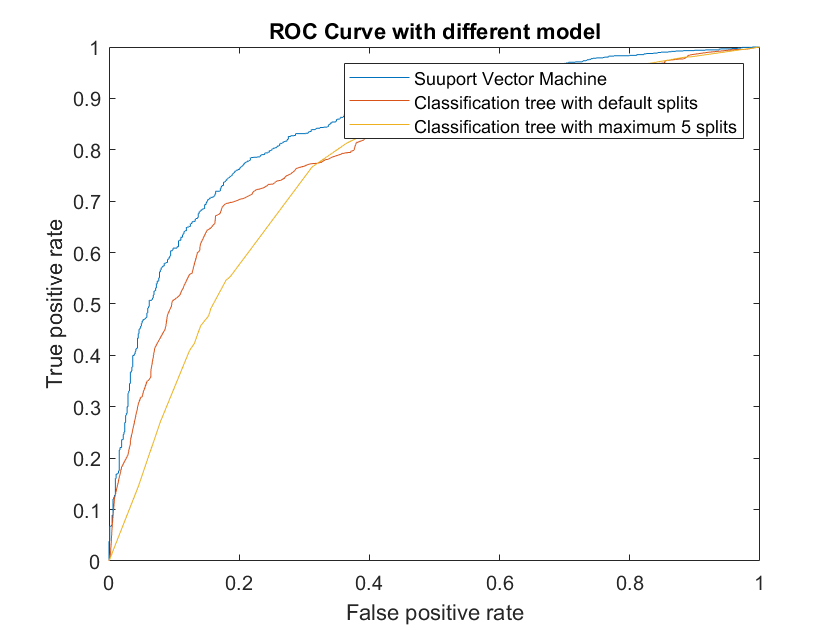

[Xt2,Yt2,~,AUCt2] = perfcurve(resp,Posterior_t2(:,2),1);

% Plotting ROC curves for the models

plot(Xsvm,Ysvm)
xlabel('False positive rate'); ylabel('True positive rate');
title('ROC Curve with different model')
hold on
plot(Xt1,Yt1)
plot(Xt2,Yt2)
legend('Suuport Vector Machine', 'Classification tree with default splits', 'Classification tree with maximum 5 splits')
hold off



% AUC for the models

AUCsvm

AUCsvm = 0.8514

AUCt1

AUCt1 = 0.8067

AUCt2

AUCt2 = 0.7674


% Final model

Final_model = fitcsvm(Xtrain,resp, 'Standardize',true,'KernelFunction', 'gaussian', 'KernelScale', 'auto', 'CVPartition', cv2)

Final_model =   ClassificationPartitionedModel
    CrossValidatedModel: 'SVM'
         PredictorNames: {'x1'  'x2'  'x3'  'x4'  'x5'  'x6'  'x7'  'x8'  'x9'  'x10'  'x11'  'x12'  'x13'  'x14'  'x15'  'x16'  'x17'  'x18'  'x19'}
           ResponseName: 'Y'
        NumObservations: 2242
                  KFold: 4
              Partition: [1×1 cvpartition]
             ClassNames: [0    1]
         ScoreTransform: 'none'


  Properties, Methods


% As both accuracy and AUC is higher for the SVM model chose that one to do
% the predictions

***sub task 3***

% 3) Confusion Matrix for the final model

predict_svm = kfoldPredict(Final_model) % predicting the response variable

predict_svm = 2242×1 categorical array
     0 
     1 
     1 
     1 
     0 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     0 
     0 
     0 
     0 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 



c_svm = confusionchart(resp,predict_svm,'RowSummary','row-normalized')

c_svm =   ConfusionMatrixChart with properties:

    NormalizedValues: [2×2 double]
         ClassLabels: [2×1 categorical]

  Show all properties


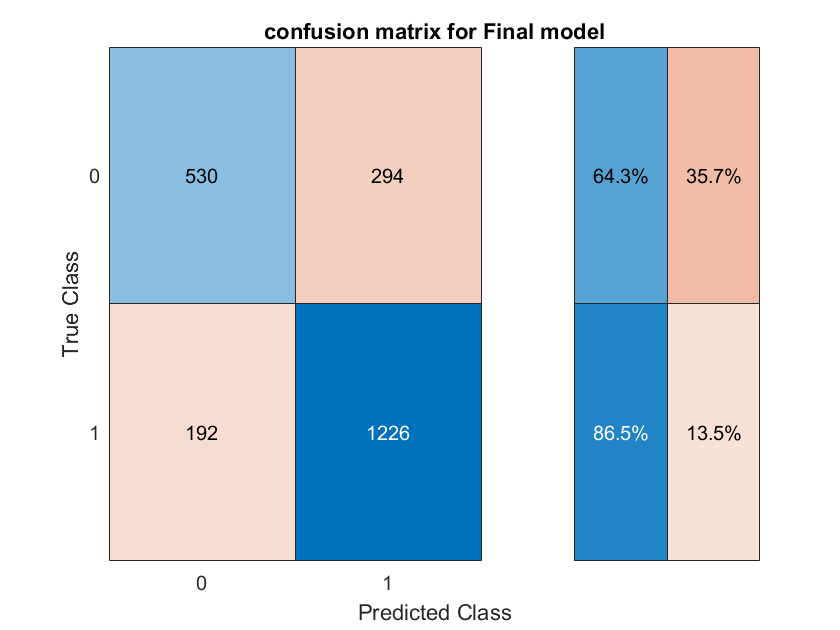

title('confusion matrix for Final model')


% Assesing the model using test data

predict_test = predict(Final_model.Trained{1,1},Xtest)

predict_test = 960×1 categorical array
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     0 
     1 
     0 
     0 
     1 
     1 
     1 
     0 
     0 
     0 
     1 
     1 
     0 
     0 
     0 
     1 
     0 
     0 
     0 
     1 
     1 



resp2 = categorical(Y1test)

resp2 = 960×1 categorical array
     0 
     0 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     0 
     0 
     0 
     0 
     1 
     0 
     0 
     0 
     0 
     0 
     1 
     1 
     0 
     0 
     0 
     1 
     0 
     0 
     0 
     1 
     1 



final_confusionmatrix = confusionchart(resp2,predict_test,'RowSummary','row-normalized')

final_confusionmatrix =   ConfusionMatrixChart with properties:

    NormalizedValues: [2×2 double]
         ClassLabels: [2×1 categorical]

  Show all properties


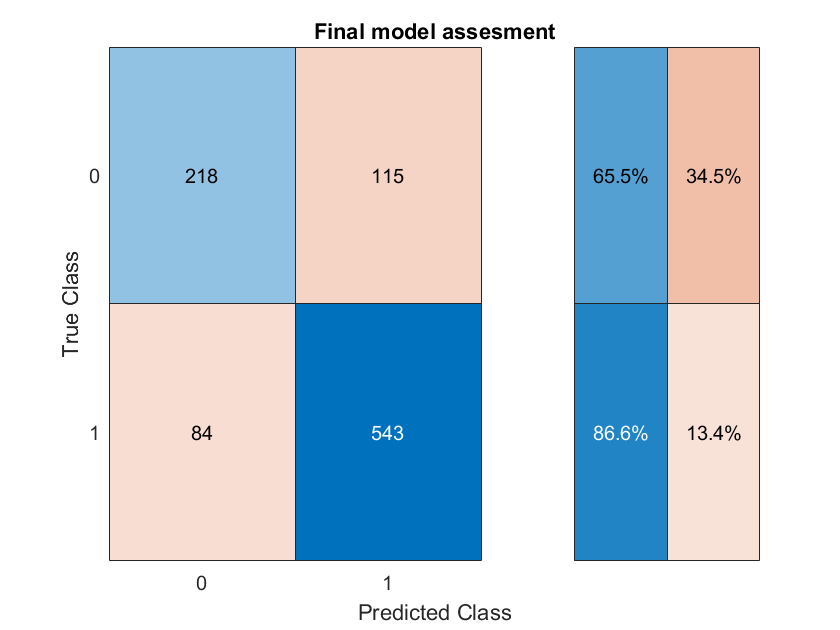

title('Final model assesment')

***sub task 4***

% 4) The process of choosing the best model

% In order to chose the better model among the 3 models that were fitted,
% initially the accuracy was taken into consideration and the model that
% gave highest accuracy was noted which is SVM model, Later based on the
% AUC calculations, again the highest AUC model was chosen and that was
% also SVM model.